# Chess set materials and views

We use ISET3d (not ISET3d-v4) to render the images in the chapter.  But ISET3d-v4 is so much faster, I created this script to use that.

Also, I used ISETCam because it has the HDR pulldown.

These notes are a reminder to BW to putt the HDR pulldown (and all the ISETCam improvements) into ISETBio.

**See also**

  isetspitschan directory

## Initialize

ieInit
if ~piDockerExists, piDockerConfig; end

## Set the chess set model

Read in the original scene.

chessR = piRecipeDefault('scene name','ChessSet');

Read 9 materials and 3 textures..


We add some new materials to the scene so we can change the chess set and board materials.

chessR = piMaterialsInsert(chessR);


Scene materials: ChessSet
-------------------------------
                name               type      
          ________________    _______________

    1     <undefined>         coateddiffuse  
    2     Black_glossy        coateddiffuse  
    3     Filt_004            diffuse        
    4     Gray                diffuse        
    5     Gray_glossy         coateddiffuse  
    6     GroundMaterial      coateddiffuse  
    7     Lyse_brikker_008    coateddiffuse  
    8     Mrke_brikker_004    coateddiffuse  
    9     Mtl                 coateddiffuse  
    10    Mtl8                diffuse        
    11    Red                 diffuse        
    12    Red_glossy          coateddiffuse  
    13 

Now set up several points of view.  We can vary these later, but first we pick one and render.

toObject = [0.03 0.05 -0.01];   % A good object
chessR.set('to',toObject);

% Top view, looking forward
topForward = [-0.0000  0.150   -0.6000];

% Top view, looking back
topBackward = [0 0.4 0.5];

% Side view
% sideView = [0.7 0.2 -0.1];
sideView = [0.5138    0.15   -0.40];

% Top view, lower, forward
topForward2 = [-0.0000  0.18   -0.6000];

% The field of view in degrees
chessR.set('fov',70);

## Choose the resolution for the rendering

highRes = false;
if ~highRes
    chessR.set('rays per pixel',64);
    chessR.set('film resolution',[256 256]);
    chessR.set('n bounces',2);
else
    chessR.set('rays per pixel',512);
    chessR.set('film resolution',[1024 1024]);
    chessR.set('n bounces',4);
end

chessR.show('objects');

                                                 material             positions (m)           sizes (m)     
                                           ____________________    ___________________    __________________

    0006ID_001_ChessSet_mesh_00001_O       {'Lyse_brikker_008'}    {'0.02 0.05 0.01' }    {'NaN NaN NaN'   }
    0009ID_001_ChessSet_mesh_00002_O       {'Mrke_brikker_004'}    {'0.02 0.05 0.01' }    {'NaN NaN NaN'   }
    0012ID_001_ChessSet_mesh_00003_O       {'Mrke_brikker_004'}    {'0.07 0.05 0.01' }    {'NaN NaN NaN'   }
    0015ID_001_ChessSet_mesh_00004_O       {'Filt_004'        }    {'0.04 0.05 -0.05'}    {'NaN NaN NaN'   }
    0018ID_001_ChessSet_mesh_00005_O       {'Filt_004'        }    {'0.02 0.05 0.01' }    {'NaN NaN NaN'   }
    0021ID_001_ChessSet_mesh_00006_O   </

*** Rendering time for ChessSet:  6.2 sec ***



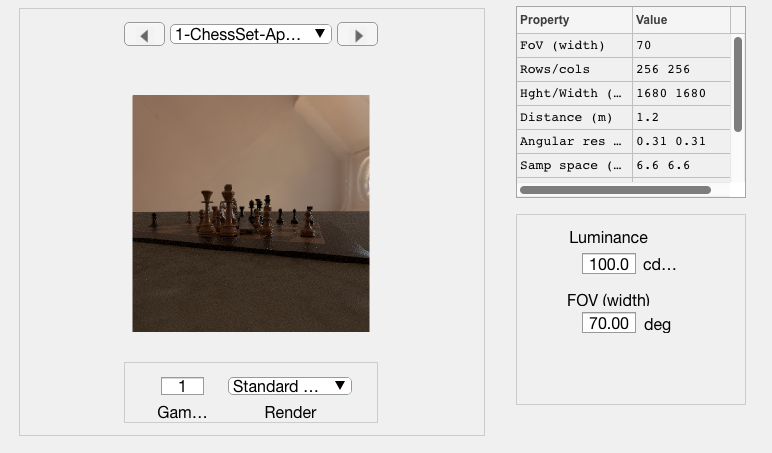

% The original scene.  
% 
% Set the display rendering to HDR!!
piWRS(chessR);

## Change the ambient lighting to be a skymap from a room

chessR.set('light', 'all', 'delete');
chessR.set('skymap','room.exr');

% TODO:  Insert code to rotate the skymap around.

## Glass and mirror

% Lyse_brikker_008 = chessR.get('material','Lyse_brikker_008');
% chessR.set('material','Lyse_brikker_008','kd val','wood');
% 
% Mrke_brikker_004 = chessR.get('material','Mrke_brikker_004');
% chessR.set('material','Mrke_brikker_004','kd val','brickwall');

chessR.set('n bounces',4);  % Needed for glass.
names = chessR.get('object names no id');
for ii=1:numel(names)
    if piContains(names{ii},'mesh')
        thisMaterial = chessR.get('asset',names{ii},'material name');
        if piContains(thisMaterial,'Lyse')
            chessR.set('asset',names{ii},'material name','glass');
        elseif piContains(thisMaterial,'Mrke')
            chessR.set('asset',names{ii},'material name','mirror');
        end
    end
end

## Do the rendering

On a GPU the low resolution rendering 

*** Rendering time for ChessSet:  80.3 sec ***



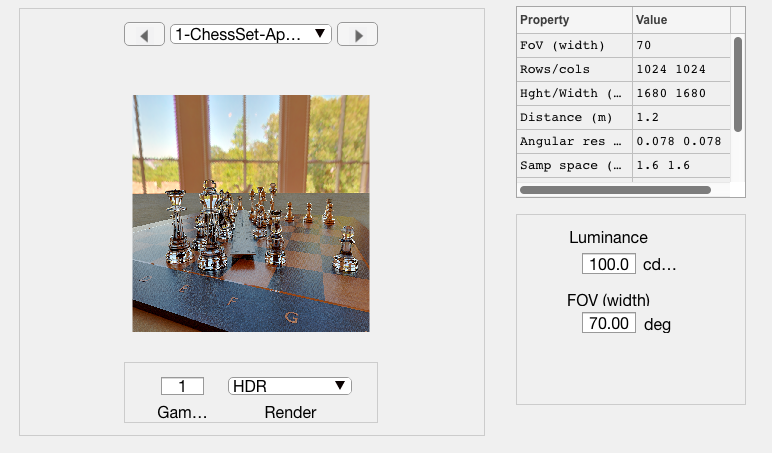

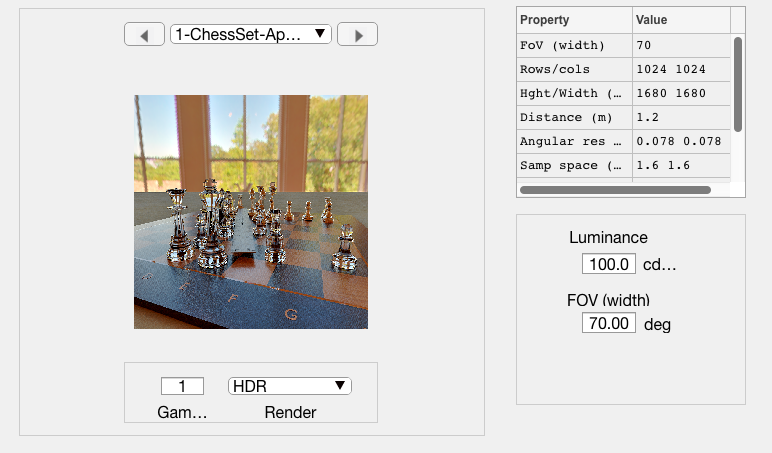

% {
tic
chessR.set('from',topForward);
chessR.set('object distance',0.35);
scene = piWRS(chessR);



%{

chessR.set('from',sideView);
chessR.set('object distance',0.35);
piWRS(chessR);

chessR.set('from',topBackward);
piWRS(chessR);

chessR.set('from',topForward2);
piWRS(chessR);
%}

## Marble and mahogany

chessR = piRecipeDefault('scene name','chess set');

Read 9 materials and 3 textures..


chessR = piMaterialsInsert(chessR);


Scene materials: ChessSet
-------------------------------
                name               type      
          ________________    _______________

    1     <undefined>         coateddiffuse  
    2     Black_glossy        coateddiffuse  
    3     Filt_004            diffuse        
    4     Gray                diffuse        
    5     Gray_glossy         coateddiffuse  
    6     GroundMaterial      coateddiffuse  
    7     Lyse_brikker_008    coateddiffuse  
    8     Mrke_brikker_004    coateddiffuse  
    9     Mtl                 coateddiffuse  
    10    Mtl8                diffuse        
    11    Red                 diffuse        
    12    Red_glossy          coateddiffuse  
    13 

chessR.set('to',toObject);
chessR.set('light', 'all','delete');  % Changed for V4
fileName = 'room.exr';
envLight = piLightCreate('background', ...
    'type', 'infinite',...
    'mapname', fileName);
chessR.set('lights', envLight,'add');  % Changed for V4                      

%{
chessR.set('rays per pixel',1024);
chessR.set('film resolution',[1024 1024]);
chessR.set('n bounces',6);
%}

names = chessR.get('object names no id');
for ii=1:numel(names)
    if piContains(names{ii},'mesh')
        thisMaterial = chessR.get('asset',names{ii},'material name');
        if piContains(thisMaterial,'Lyse')
            chessR.set('asset',names{ii},'material name','marbleBeige');
        elseif piContains(thisMaterial,'Mrke')
            chessR.set('asset',names{ii},'material name','mahogany_dark');
        end
    end
end

% These worked, too.
% chessR.set('material','planeTan','kd val','wood001');
% chessR.set('material','planeTan','kd val','wood002');
% chessR.set('material','planeTan','kd val','marbleBeige');

% For some reason, GroundMaterial gets a random number attached to it.
n = chessR.get('object names');
ii = find(piContains(n,'GroundMaterial'));
chessR.set('asset',n{ii},'material name','wood001');

## Mahogany series

chessR.set('light', 'background', 'world orientation', [-90, -45, 0]);

% {
chessR.set('from',topForward);
tic
piWRS(chessR);

*** Rendering time for ChessSet:  6.4 sec ***



toc

Elapsed time is 15.251951 seconds.


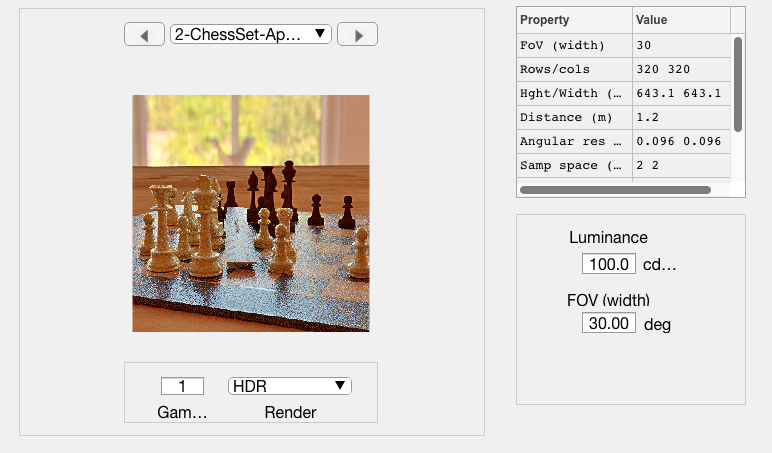

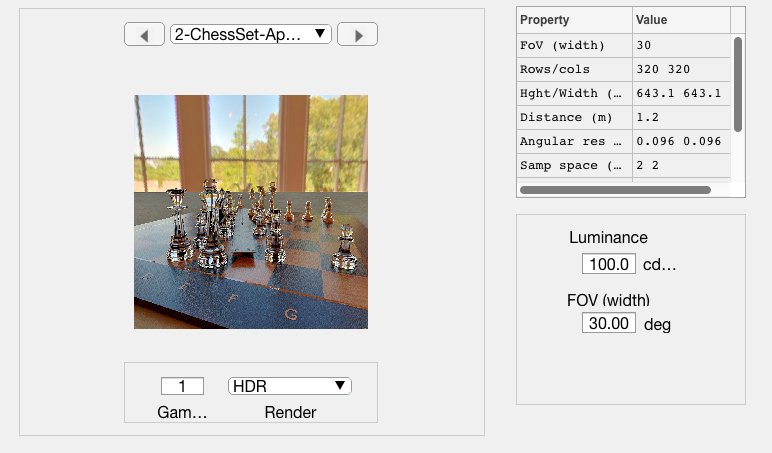

sceneSet(scene,'display mode','hdr');


%{
chessR.set('from',sideView);
piWRS(chessR);

chessR.set('from',topBackward);
piWRS(chessR);

chessR.set('from',topForward2);
piWRS(chessR);
%}

## END